# Atividade 11

Otávio Baziewicz Filho - 1942808

clc; clear; close all;

## Segmentação

Faça um script para segmentar as cerejas da imagem **greens.jpg** abaixo. Utilize o seguinte método: operações globais entre os canais de cores R, G e B.

Observe os canais R, G e B individualmente para decidir que tipo de combinação entre os canais é mais promissora. Talvez nem seja necessário usar os três canais. Não complique, é uma operação simples! Mostre o resultado final das seguintes formas: 

a) uma máscara binária

b) uma sobreposição da máscara binária sobre a imagem, de forma a manter as cerejas e eliminar (deixar totalmente preto) o resto

c) um contorno amarelo de largura maior que 2 pixels nas regiões com cerejas.

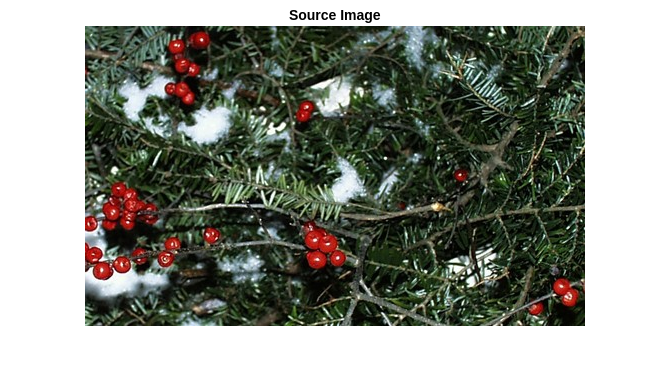

img = imread("greens.jpg");

r = img(:,:,1);
g = img(:,:,2);
b = img(:,:,3);

% A)
cherry = imsubtract(r,g);
cherryBw = imbinarize(cherry, graythresh(cherry));
cherryBw = imclose(cherryBw, strel("square", 7));
cherryBw = imopen(cherryBw, strel("square", 3));
% cherryBw = imfill(cherryBw, "holes"); % Nao foi significativo

% B)    
cherryBwD = double(cherryBw);
segCherry = uint8(double(img) .* repmat(cherryBwD, [1 1 3]));

% C)
cherryPerimBw = bwperim(cherryBw, 8);
rSat = r;
gSat = g;
rSat(cherryPerimBw) = 255;
gSat(cherryPerimBw) = 255;
imgWithYellowPerim = cat(3, rSat, gSat, b);



figure, imshow(img)
title("Source Image")

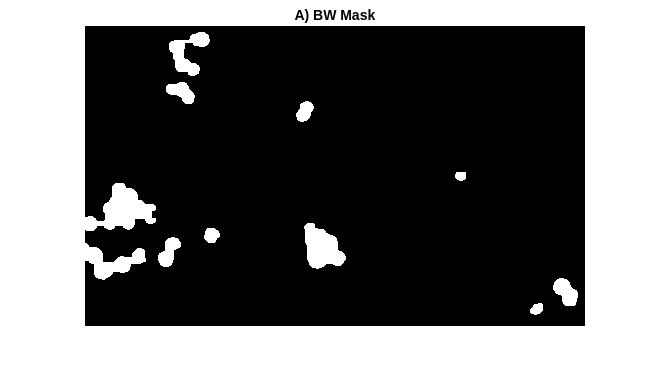


figure, imshow(cherryBw)
title("A) BW Mask")

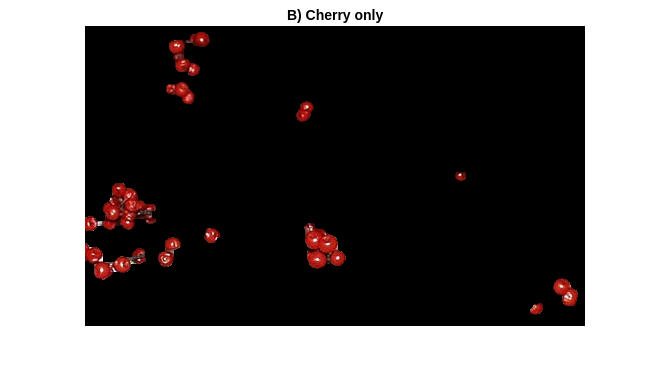


figure, imshow(segCherry)
title("B) Cherry only")

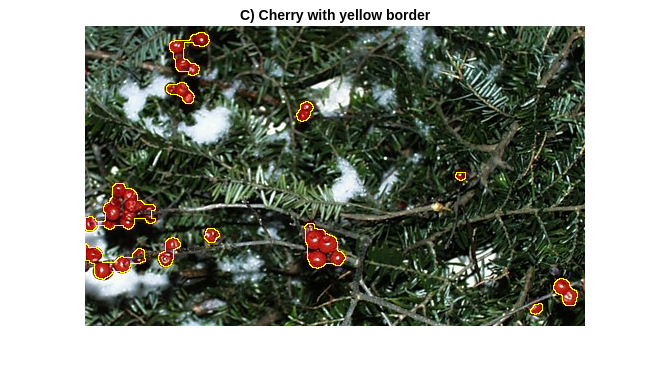


figure, imshow(imgWithYellowPerim)
title("C) Cherry with yellow border")

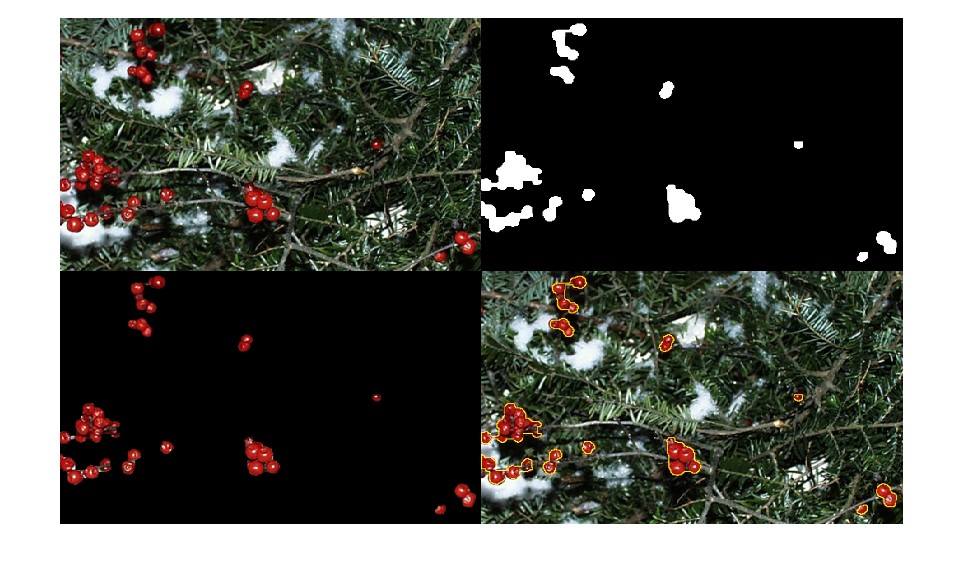


figure, montage({ img, cherryBw, segCherry, imgWithYellowPerim}, "Size", [2 2])